# Proyecto de optimización de redes cerradas (IME-425)

Datos de la red hidráulica adaptados del caso de estudio 3: G. H. B. Cassiolato, E. P. Carvalho, J. A. Caballero, and M. A. S. S. Ravagnani, “Optimization of water distribution networks using a deterministic approach,” *Engineering Optimization*, vol. 53, no. 1, pp. 107–124, 2021, doi: 10.1080/0305215X.2019.1702980.

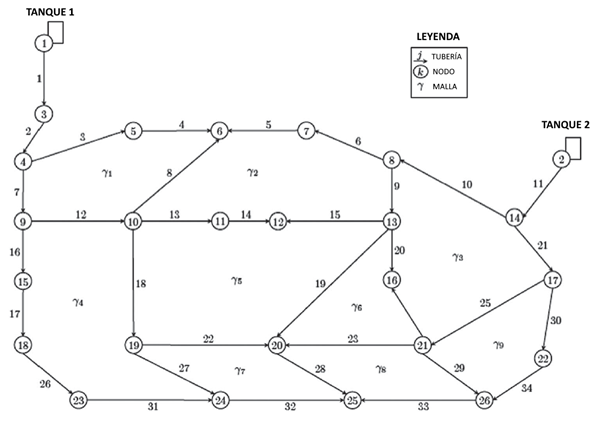

## Datos generales de la red hidráulica

En el archivo **datos_generales.mat** se tiene una estructura guardada con las siguientes variables:

- **L**: Longitudes de las tuberías, m (34 x 1)

- **Qn**: Demandas nodales, m³/min (26 x 1)

- **h_min**: Cabezas nodales mínimas, m (26 x 1)

- **D_lista**: Diámetros comerciales, m (14 x 1)

- **C_lista**: Costos unitarios, USD/m (14 x 1)

## Funciones externas requeridas para la optimización

- **red_cerrada: **Calcula las ecuaciones conservativas, las cabezas nodales y la velocidad máxima para un conjunto de diámetros y caudales.

- **caudales**: Calcula los caudales requeridos para satisfacer las ecuaciones conservativas, para un conjunto de diámetros determinado.

- **costo_total**: Calcula el costo total de las tuberías, para un conjunto de diámetros determinado.

- **restricciones**: Verifica las restricciones de cabezas nodales mínimas y la velocidad máxima, para un conjunto de diámetros determinado.

## Optimización

n_var=34;
int_vars=1:34;

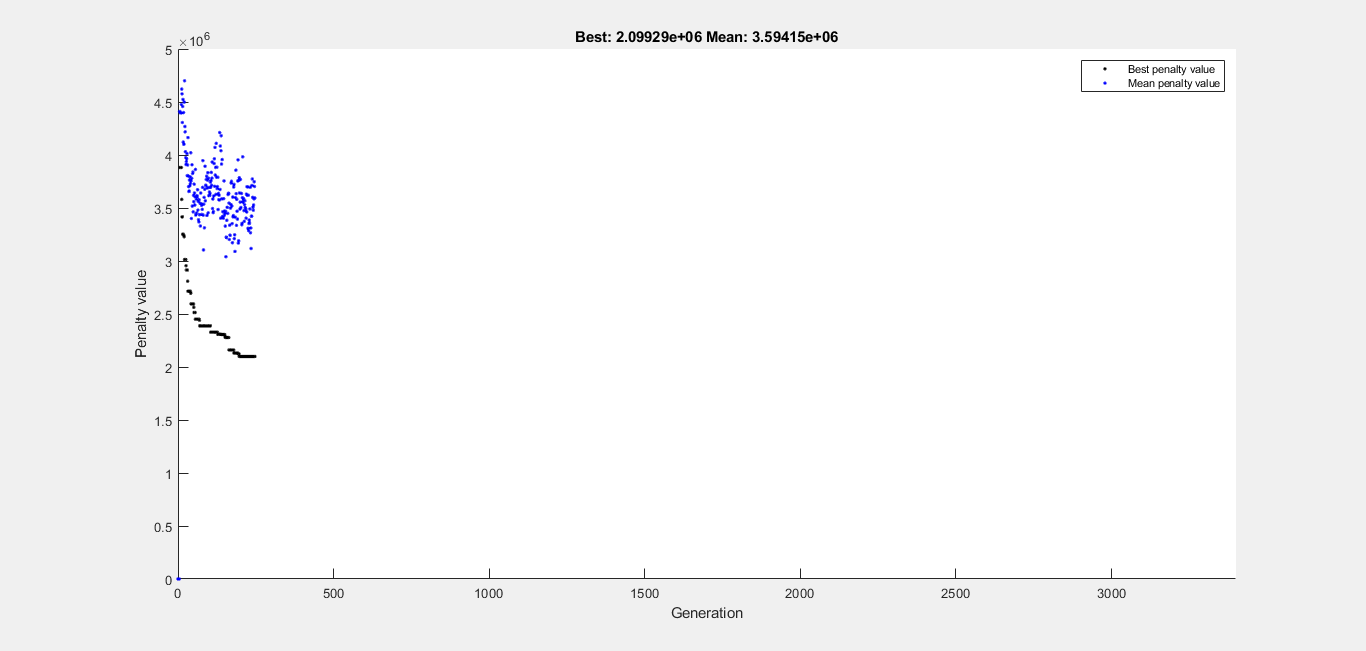

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


% Set nondefault solver options
options2 = optimoptions('ga','UseParallel',true,'PlotFcn','gaplotbestf');


% Solve
[iD_opt,costo_min] = ga(@costo_total,n_var,[],[],[],[],ones(n_var,1),...
    repmat(14,n_var,1),@restricciones,int_vars,options2);

% Clear variables
clearvars options2

Diámetros óptimos (m)


D_opt =     1.0000
    0.8000
    0.3000
    0.3000
    0.2500
    0.4500
    0.7000
    0.2000
    0.7000
    0.9000


Costo mínimo (USD):
   2.0993e+06



## Resultados de la optimización

D_opt=iD_opt'; load("datos_generales.mat","D_lista","h_min");
for i=1:34

Q_opt =    82.1732
   63.7732
    7.2499
    0.7499
    2.6246
    5.7246
   52.0232
    0.8254
   39.0501
   50.9747


    D_opt(i)=D_lista(iD_opt(i));

error = 1.0e-12 *

         0
    0.0071
         0
         0
         0
   -0.0044
         0
         0
   -0.0018
   -0.0018


h_opt =   100.0000
   95.0000
   99.3027
   95.7692
   87.1928
   87.0931
   92.5647
   93.0553
   91.2389
   88.7385


Vmax = 2.2530

end

rest =          0
         0
  -14.3027
  -10.7692
   -2.1928
   -2.0931
  -10.5647
  -11.0553
   -6.2389
   -3.7385


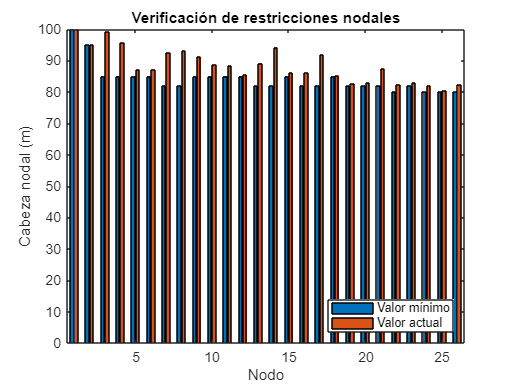

disp('Diámetros óptimos (m)'); D_opt
disp('Costo mínimo (USD):'); disp(costo_min);

Q_opt = caudales(D_opt)
[error,h_opt,Vmax]=red_cerrada(Q_opt,D_opt)
[rest,~]=restricciones(iD_opt)

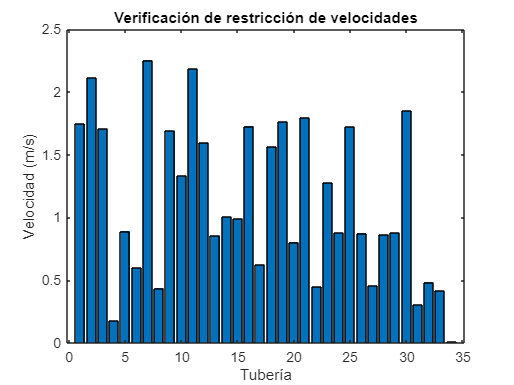


% Gráficos de cabezas nodales
cabezas=[h_min h_opt];
figure(2); graf_barras1=bar(cabezas); 
xlabel('Nodo'); ylabel('Cabeza nodal (m)'); title('Verificación de restricciones nodales');

set(graf_barras1, {'DisplayName'}, {'Valor mínimo','Valor actual'}');legend('Location','southeast')

% Gráficos de velocidades
V=abs((1/60*Q_opt)./(pi/4.*D_opt.^2));
figure(3); graf_barras2=bar(V); 
xlabel('Tubería'); ylabel('Velocidad (m/s)'); title('Verificación de restricción de velocidades');